clc
clear all

## **Initializig the space and generating signature (2,2)**

clifford_signature(0,0)
%I = [1];
%G_1,1

E1 = [0 1;1 0];
E2 = [0 -1;1 0];
I = [1 0;0 1];
%G(2,2)

E1 = [E1 zeros(size(E1)); zeros(size(E1)) -E1]; 
E2 = [E2 zeros(size(E2)); zeros(size(E2)) -E2] ;
E3 = [zeros(size(I)) I; I  zeros(size(I))]; 
E4 = [zeros(size(I)) -I; I  zeros(size(I))]; 
I = [I zeros(size(I)); zeros(size(I)) I];
F = E2;
E2 = E3;
E3 = F;
%G(3,3)
E1 = [E1 zeros(size(E1)); zeros(size(E1)) -E1] ;
E2 = [E2 zeros(size(E2)); zeros(size(E2)) -E2] ;
E3 = [E3 zeros(size(E3)); zeros(size(E3)) -E3] ;
E4 = [E4 zeros(size(E4)); zeros(size(E4)) -E4];
E5 = [zeros(size(I)) I; I  zeros(size(I))] ;
E6 = [zeros(size(I)) -I; I  zeros(size(I))] ;
I = [I zeros(size(I)); zeros(size(I)) I];

F = E5;
E5 = E3;
E3 = F;

%G(4,4)
E1 = [E1 zeros(size(E1)); zeros(size(E1)) -E1] ;
E2 = [E2 zeros(size(E2)); zeros(size(E2)) -E2] ;
E3 = [E3 zeros(size(E3)); zeros(size(E3)) -E3] ;
E4 = [E4 zeros(size(E4)); zeros(size(E4)) -E4];
E5 = [E5 zeros(size(E5)); zeros(size(E5)) -E5] ;
E6 = [E6 zeros(size(E6)); zeros(size(E6)) -E6];
E7 = [zeros(size(I)) I; I  zeros(size(I))] ;
E8 = [zeros(size(I)) -I; I  zeros(size(I))] ;
I = [I zeros(size(I)); zeros(size(I)) I];

F = E7;
E7 = E4;
E4 = F;

## Generating signature (8,0)

%G(5,3) q+1,p-1
F1 = E1*E5;
F2 = E1*E6;
F3 = E1*E7;
F4 = E1*E8;
F5 = E1;
F6 = E1*E2;
F7 = E1*E3;
F8 = E1*E4;
%G(1,7) p-4,q+4
E1 = F1;
E2 = F2;
E3 = F3;
E4 = F4;
E5 = F5;
E6 = F6;
E7 = F7;
E8 = F8;

F1 = E1;
F2 = E2*E3*E4*E5*E2;
F3 = E2*E3*E4*E5*E3;
F4 = E2*E3*E4*E5*E4;
F5 = E2*E3*E4*E5*E5;
F6 = E6;
F7 = E7;
F8 = E8;



%G(8,0) q+1,p-1  q = 7 p = 1
E1 = F1;
E2 = F2;
E3 = F3;
E4 = F4;
E5 = F5;
E6 = F6;
E7 = F7;
E8 = F8;

F1 = E1*E2;
F2 = E1*E3;
F3 = E1*E4;
F4 = E1*E5;
F5 = E1*E6;
F6 = E1*E7;
F7 = E1*E8;
F8 = E1;

## Defining the Witt basis

%% Sudoku 
f1 = 0.5*(F1 + i*F2); 
f1T = 0.5*(F1 - i*F2); 
f2 = 0.5*(F3 + i*F4); 
f2T = 0.5*(F3 - i*F4);
f3 = 0.5*(F5 + i*F6); 
f3T = 0.5*(F5 - i*F6); 
f4 = 0.5*(F7 + i*F8); 
f4T = 0.5*(F7 - i*F8);

## Defining the states of the 4 qubit system

%// Element "I"
Id = f1*f1T*f2*f2T*f3*f3T*f4*f4T;
%// ket basis vectors multiplied by "Id" 11 
ket0000 = 1*Id;
ket0001 = f4T*Id

ket0001 =    0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.1250i   0.0000 - 0.1250i
   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.1250i   0.0000 - 0.1250i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000

ket0010 = f3T*Id;
ket0100 = f2T*Id;
ket0011 = f3T*f4T*Id;
ket0101 = f2T*f4T*Id;
ket0110 = f2T*f3T*Id;
ket0111 = f2T*f3T*f4T*Id;
ket1000 = f1T*Id;
ket1001 = f1T*f4T*Id

ket1001 =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.1250 + 0.0000i  -0.1250 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i
  -0.1250 + 0.0000i   0.1250 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000

ket1010 = f1T*f3T*Id;
ket1100 = f1T*f2T*Id;
ket1011 = f1T*f3T*f4T*Id;
ket1101 = f1T*f2T*f4T*Id;
ket1110 = f1T*f2T*f3T*Id;
ket1111 = f1T*f2T*f3T*f4T*Id;


## Gate implementations

%// Not operation
not1 = f1 +f1T;
not2 = f2 +f2T;
not3 = f3 +f3T;
not4 = f4 +f4T;
%//controlled z
cz12 = f1*f1T + f1T*f1*f2*f2T - f1T*f1*f2T*f2;
cz13 = f1*f1T + f1T*f1*f3*f3T - f1T*f1*f3T*f3;
cz24 = f2*f2T + f2T*f2*f4*f4T - f2T*f2*f4T*f4;
cz34 = f3*f3T + f3T*f3*f4*f4T - f3T*f3*f4T*f4;

%//hadamard
h1 = (1/sqrt(2))*(f1*f1T + f1  + f1T - f1T*f1);
h2 = (1/sqrt(2))*(f2*f2T + f2  + f2T - f2T*f2);
h3 = (1/sqrt(2))*(f3*f3T + f3  + f3T - f3T*f3);
h4 = (1/sqrt(2))*(f4*f4T + f4  + f4T - f4T*f4);

## Oracle function

%//superposition
psi = h1*h2*h3*h4*ket0000

psi =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.1250 + 0.0000i  -0.1250 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.1250 + 0.0000i   0.1250 + 0.0000i
   0.0000 - 0.1250i   0.0000 + 0.1250i   0.0000 + 0.0000i   0.0000 + 0.0000i   


%//oracle
psi1 = psi;
%//12
psi1 = not1*cz12*not1*psi1;
%//13
psi1 = not3*cz13*not3*psi1;
%//24
psi1 = not2*cz24*not2*psi1;
%34
psi1 = not4*cz34*not4*psi1;
%multi controlled z
mcz = f1*f1T + f1T*f1*(f2*f2T + f2T*f2*(f3*f3T + f3T*f3*(f4*f4T - f4T*f4)));
psi1 = mcz*psi1;
psi1 = mcz*not4*not3*not2*not1*psi1;
psi1 = not1*not2*not3*not4*psi1;
psi1 = -1*psi1;


## Diffusion operator

%//diffusion
diffusion  = h1*h2*h3*h4*not1*not2*not3*not4*mcz*not4*not3*not2*not1*h4*h3*h2*h1;
%diffusion  = h4*h3*h2*h1*not4*not3*not2*not1*h4*Toff4*h4*not1*not2*not3*not4*h1*h2*h3*h4;
psi2 = diffusion*psi1;
%psi2 = psi2;

## Repeating the Grover application

psi1 = -psi2;
%//12
psi1 = not1*cz12*not1*psi1;
%//13
psi1 = not3*cz13*not3*psi1;
%//24
psi1 = not2*cz24*not2*psi1;
%34
psi1 = not4*cz34*not4*psi1;
%multi controlled z
mcz = f1*f1T + f1T*f1*(f2*f2T + f2T*f2*(f3*f3T + f3T*f3*(f4*f4T - f4T*f4)));
psi1 = mcz*psi1;
psi1 = mcz*not4*not3*not2*not1*psi1;
psi1 = not1*not2*not3*not4*psi1;
psi1 = -1*psi1

psi1 =    0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i
  -0.0312 - 0.0937i   0.0312 + 0.0937i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0937 + 0.0312i   0.0937 - 0.0312i  -0.0937 + 0.0312i   0.0937 - 0.0312i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0312 + 0.0937i  -0.0312 - 0.0937i
   0.0937 + 0.0312i  -0.0937 - 0.0312i   0.0000 + 0.0000i   0.0000 + 0.0000i  


%//diffusion
diffusion  = h1*h2*h3*h4*not1*not2*not3*not4*mcz*not4*not3*not2*not1*h4*h3*h2*h1;
%diffusion  = h4*h3*h2*h1*not4*not3*not2*not1*h4*Toff4*h4*not1*not2*not3*not4*h1*h2*h3*h4;
psi2 = diffusion*psi1

psi2 =    0.0000 - 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 - 0.0000i
  -0.0000 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i  -0.0000 - 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 - 0.0000i  -0.0000 + 0.0000i
  -0.0625 - 0.0937i   0.0625 + 0.0937i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0937 + 0.0625i   0.0937 - 0.0625i  -0.0937 + 0.0625i   0.0937 - 0.0625i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0625 + 0.0937i  -0.0625 - 0.0937i
   0.0937 + 0.0625i  -0.0937 - 0.0625i   0.0000 + 0.0000i   0.0000 + 0.0000i  

## **Plotting of the results**

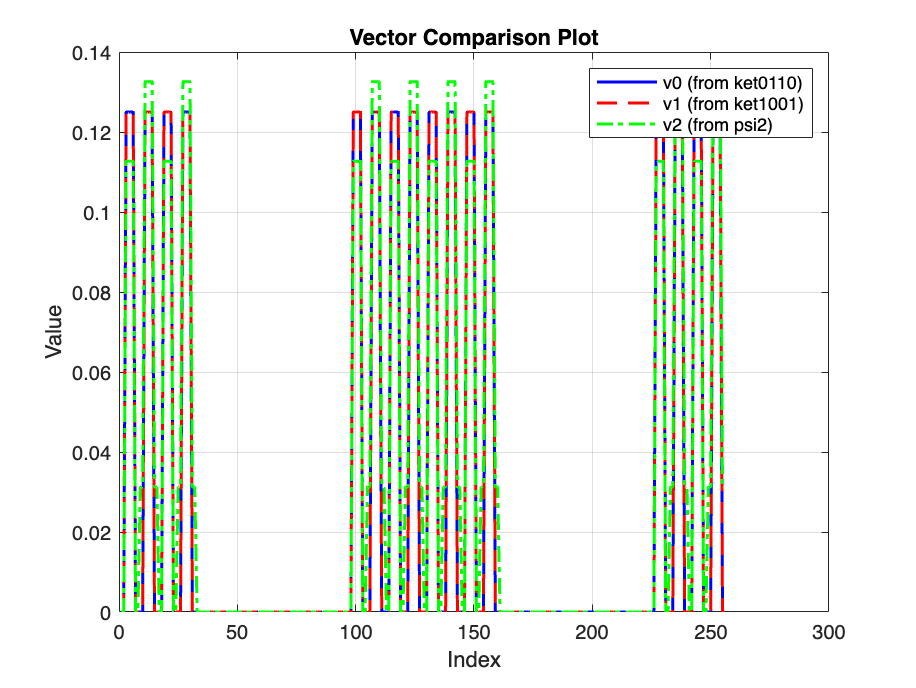

v0 = abs(ket0110(:)); % Flatten the whole matrix to a vector
%v1 = abs(ket1001(:,1));
v1 = abs(ket1001(:));
%v2 = abs(psi2(:,1));
v2 = abs(psi2(:));

% Assume v0, v1, v2 are column vectors of same length
plot(1:length(v0), v0, 'b-', ...
     1:length(v1), v1, 'r--', ...
     1:length(v2), v2, 'g-.', 'LineWidth', 1.5);
legend('v0 (from ket0110)', 'v1 (from ket1001)', 'v2 (from psi2)');
xlabel('Index');
ylabel('Value');
title('Vector Comparison Plot');
grid on;